## Middle Interval [1, 1000] anlaysis

#### Compare the number of guesses people take to the number of guesses a bisection search algorith would take

MAX = 1000; % endpoint of interval (depends on which experiment)
% logical vector of whether person knows bisection search
class = logical([1, 1, 0, 0, 1, 0, 1, 0, 0, 1, 0, 1, 1, 1, 0, 1, 0, 1,...
    1, 1, 1, 1, 0, 0, 1, 0, 1, 1, 0, 0, 0, 1, 0, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1]); % 1 if participant knew Bisection Search

people_nTurns = [12, 9, 16, 15, 12, 8, 3, 4, 12, 10, 13, 8, 15, 11, 10, 16,...
    20, 13, 10, 9, 11, 9, 7, 20, 28, 10, 13, 10, 9, 11, 34, 13, 8, 25, 13, 9, 10, 6, 10, 8, 12, 10, 10]';

machine_nTurns = [10, 10, 8, 8, 9, 10, 3, 9, 9, 8, 10, 10, 8, 10, 9, 9, 10, 8, 10, ...
    8, 8, 9, 10, 8, 8, 10, 10, 8, 10, 7, 10, 8, 10, 8, 10, 10, 6, 8, 8, 9, 6, 8, 8]'; 
% Bisection Search has worst-case complexity of O(logN). note that 10 ~= log(1000)

[mean(people_nTurns), var(people_nTurns)]
[mean(machine_nTurns),  var(machine_nTurns)]

figure
boxplot([people_nTurns, machine_nTurns],'Notch','on','Labels', ...
    {'People (mu=12.1, var=34.4)', 'Bisection Search algorithm (mu=8.7, var=2.0)'})
ylabel('No. of Guesses')
title("Number of guesses until game end: Humans vs Algorithm")
hold off

% PERFORM One-way anova on machine vs people
% ANOVA is based on the assumption that all sample populations are normally distributed. 
[p,tbl,stats] = anova1([people_nTurns, machine_nTurns])
hold off

#### Look at the absolute deviation of people from an EIG maximizing agent

% a cell array of the absolute errors from imformation maximizing bisection
% search at each guess
deltas = {[90, 45, 25, 49, 0, 0, 3, 2, 0, 1, 1, 0] ;
[0, 0, 0, 33, 0, 0, 1, 0, 0] ;
[493, 414, 156, 106, 126, 10, 10, 17, 15, 12, 8, 7, 12, 10, 5, 0] ;
[100, 250, 0, 7, 5, 6, 6, 5, 5, 4, 4, 3, 3, 1, 1] ;
[0, 0, 0, 12, 0, 7, 5, 9, 8, 7, 2, 1] ;
[300, 300, 250, 0, 0, 2, 2, 0] ;
[0, 0, 0] ;
[431, 166, 36, 94] ;
[0, 150, 100, 50, 0, 0, 3, 2, 0, 2, 1, 1] ;
[0, 0, 0, 7, 0, 0, 0, 0, 0, 0] ;
[478, 421, 25, 105, 70, 5, 40, 1, 4, 3, 3, 2, 2] ;
[0, 0, 25, 0, 5, 5, 0, 1] ;
[444, 450, 454, 132, 68, 84, 0, 0, 5, 5, 0, 5, 0, 0, 0] ;
[0, 0, 25, 25, 0, 0, 3, 3, 0, 0, 0] ;
[400, 450, 50, 150, 100, 0, 5, 5, 4, 1] ;
[0, 0, 0, 12, 0, 3, 0, 8, 6, 5, 4, 3, 22, 10, 4, 1] ;
[300, 300, 250, 200, 150, 100, 50, 0, 0, 3, 13, 9, 10, 11, 12, 13, 7, 3, 0, 1] ;
[491, 479, 412, 50, 0, 0, 0, 0, 5, 2, 0, 0, 0] ;
[0, 0, 0, 2, 5, 2, 3, 0, 0, 0] ;
[0, 0, 0, 22, 22, 22, 17, 12, 2] ;
[0, 0, 75, 0, 0, 0, 7, 0, 0, 2, 1] ;
[0, 150, 100, 50, 30, 16, 8, 0, 0] ;
[377, 338, 16, 5, 2, 1, 1] ;
[498, 440, 369, 1000, 1000, 355, 388, 112, 62, 0, 0, 75, 25, 5, 5, 0, 4, 3, 3, 2] ;
[499, 496, 493, 1000, 4, 54, 100, 115, 100, 70, 10, 0, 54, 45, 40, 39, 25, 15, 0, 0, 5, 0, 2, 0, 1, 1, 1, 0] ;
[200, 100, 25, 25, 25, 0, 0, 3, 0, 1] ;
[455, 457, 382, 575, 175, 75, 0, 50, 6, 4, 1, 1, 1] ;
[250, 250, 287, 250, 0, 7, 0, 0, 0, 0] ;
[0, 0, 25, 25, 0, 0, 1, 1, 1] ;
[266, 273, 23, 6, 11, 8, 12, 8, 1, 1, 0] ;
[261, 64, 77, 74, 69, 63, 100, 0, 5, 10, 10, 7, 12, 7, 6, 5, 4, 3, 378, 278, 178, 78, 28, 22, 3, 7, 5, 4, 3, 2, 1, 1, 0, 0] ;
[0, 0, 75, 0, 0, 0, 13, 10, 10, 10, 9, 5, 1] ;
[421, 39, 0, 0, 12, 0, 3, 1] ;
[493, 403, 1000, 650, 200, 25, 25, 0, 10, 10, 100, 10, 5, 0, 0, 11, 11, 10, 9, 8, 7, 6, 3, 0, 0] ;
[0, 0, 25, 50, 0, 0, 10, 8, 0, 0, 2, 1, 1] ;
[0, 50, 50, 0, 15, 14, 13, 5, 0] ;
[0, 0, 0, 12, 2, 3, 1, 1, 0, 0] ;
[0, 100, 0, 12, 2, 2] ;
[0, 0, 25, 0, 0, 7, 0, 0, 2, 1] ;
[29, 164, 114, 21, 1, 3, 2, 0] ;
[264, 118, 35, 47, 35, 25, 23, 0, 5, 5, 2, 4] ;
[0, 0, 25, 0, 0, 3, 3, 0, 0, 0] ;
[0, 0, 0, 3, 7, 0, 0, 5, 0, 1]};

maxTurns = max(cellfun(@length, deltas));
% a matrix of where each column is a participant's error sequence
M = nan(length(deltas), maxTurns);
% plot the trajectory of the errors (both types of people)
figure
hold on
for i = 1:length(deltas)
    M(i, 1:length(deltas{i})) = deltas{i}/MAX; % normalized to [0, 1]
    % plot the normalized absolute error
    h = plot(M(i, :), 'LineWidth', 0.5, ...
        'Color', 'cyan', 'HandleVisibility', 'off');
    if i == length(deltas)
        h.HandleVisibility = 'on';
    end
end
M = M';
% create an array of the normalized delta averages
average_deltas = nanmedian(M,2);

% indicate where pure bisection search would have stopped
xline(max(machine_nTurns), ':k', 'worst case of pure bisection search', ...
    'LabelHorizontalAlignment', 'left', 'LineWidth', 2, ...
    'HandleVisibility', 'off');

% plot the smoothed average error sequence
smoothFit = fit([1:length(average_deltas)]', average_deltas, 'smoothingspline');
h = plot(smoothFit); h.LineWidth = 1; h.LineStyle = '-'; h.Color = 'blue';
% plot the linear regression function
linearFit = fit([1:length(average_deltas)]', average_deltas, 'poly1');
h = plot(linearFit); h.LineWidth = 1.5; h.LineStyle = '-'; h.Color = 'black';
% plot the power regression funtion
powerFit = fit([1:length(average_deltas)]', average_deltas, 'power2');
h = plot(powerFit); h.LineWidth = 1.5; h.LineStyle = '-'; h.Color = 'magenta';
% overlay a boxplot showing the conditional expectation
boxplot(M', 'PlotStyle', 'traditional')
% label plot and axes nad add legend
title("Sequence of deltas between human guesses vs EIG maximizing agent")
ylim([0, 0.5])
ylabel('Absolute error (normalized)')
xlabel('Time (guess #)')
legend('individual', 'smooth median', 'linear regression', 'power series model');
hold off 

% PERFORM One-way anova on timepoints
% ANOVA is based on the assumption that all sample populations are normally distributed.
[p,tbl,stats] = anova1(M')
% n = length(class); % number of participants
% BtwnFactors = arrayfun(@(x) strcat('participant', num2str(x)), [1:n]', 'UniformOutput', false);
% responses = arrayfun(@(x) strcat('timept', num2str(x)), [1:maxTurns]', 'UniformOutput', false); % these are the timepoints
% t = array2table(M', 'VariableNames', responses); % create table for anova
% t.participant = BtwnFactors; % so now I have a table.
% % Fit a repeated measures model, where the timepoints are the responses and the participant is the predictor variable.
% Meas = table([1:maxTurns]','VariableNames',{'Measurements'})
% rm = fitrm(t,'timept1-timept34~participant','WithinDesign',Meas)
hold off

#### Analyze the inear regression slope and intercept

linearSlope = linearFit.p1
linearIntercept = linearFit.p2
% observe that you get the same thing if you solve 'by hand'
X = [ones(length(average_deltas),1), [1:maxTurns]'];
Y = average_deltas;
X\Y % solving linear regression with matrices

## Big Interval [1, 100000] anlaysis

MAX = 100000; % endpoint of interval (depends on which experiment)
% logical vector of whether person knows bisection search
class = logical([0, 1, 1, 0, 1, 0, 1, 1, 0, 1, 1, 1, 0, 1, ...
    0, 0, 1, 0, 1, 1, 0, 0, 1]); % 1 if participant knew Bisection Search

people_nTurns = [25, 32, 20, 39, 18, 68, 27, 35, 38, 18, 20, ...
    19, 37, 16, 23, 13, 48, 36, 17, 22, 21, 39, 43]';

machine_nTurns = [17, 15, 15, 17, 17, 17, 17, 17, 16, 17, ...
    16, 17, 17, 16, 16, 16, 16, 17, 16, 15, 16, 17, 16]'; 
% Bisection Search has worst-case complexity of O(logN). note that 17 ~= log(100,000)

[mean(people_nTurns), var(people_nTurns)]

ans =    29.3043  170.7668


[mean(machine_nTurns),  var(machine_nTurns)]

ans =    16.3478    0.5099


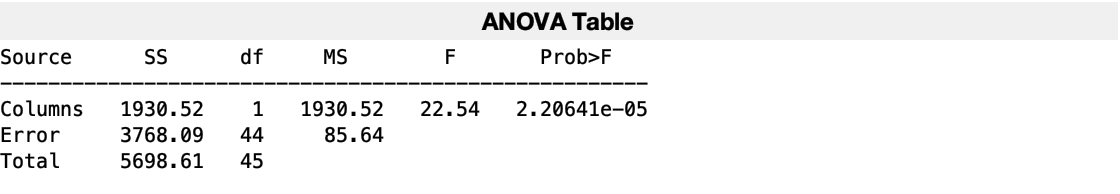

p = 2.2064e-05

tbl = 4×6 cell array
    {'Source' }    {'SS'        }    {'df'}    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[1.9305e+03]}    {[ 1]}    {[1.9305e+03]}    {[ 22.5427]}    {[2.2064e-05]}
    {'Error'  }    {[3.7681e+03]}    {[44]}    {[   85.6383]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[5.6986e+03]}    {[45]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [2×1 char]
         n: [23 23]
    source: 'anova1'
     means: [29.3043 16.3478]
        df: 44
         s: 9.2541



figure
boxplot([people_nTurns, machine_nTurns],'Notch','on','Labels', ...
    {'People (mu=29.3, var=170.8)', 'Bisection Search algorithm (mu=16.3, var=0.6)'})
ylabel('No. of Guesses')
title("Number of guesses until game end: Humans vs Algorithm")
hold off

% PERFORM One-way anova on machine vs people
% ANOVA is based on the assumption that all sample populations are normally distributed.
[p,tbl,stats] = anova1([people_nTurns, machine_nTurns])

#### Look at the absolute deviation of people from an EIG maximizing agent

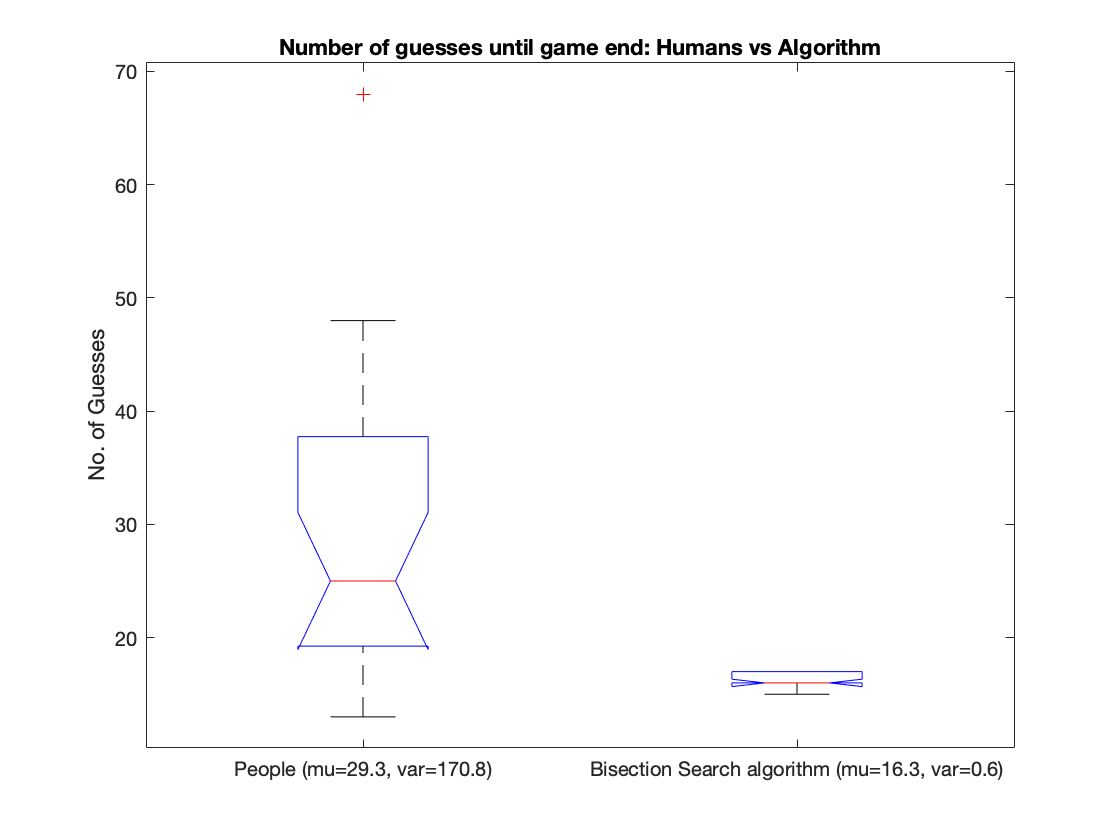

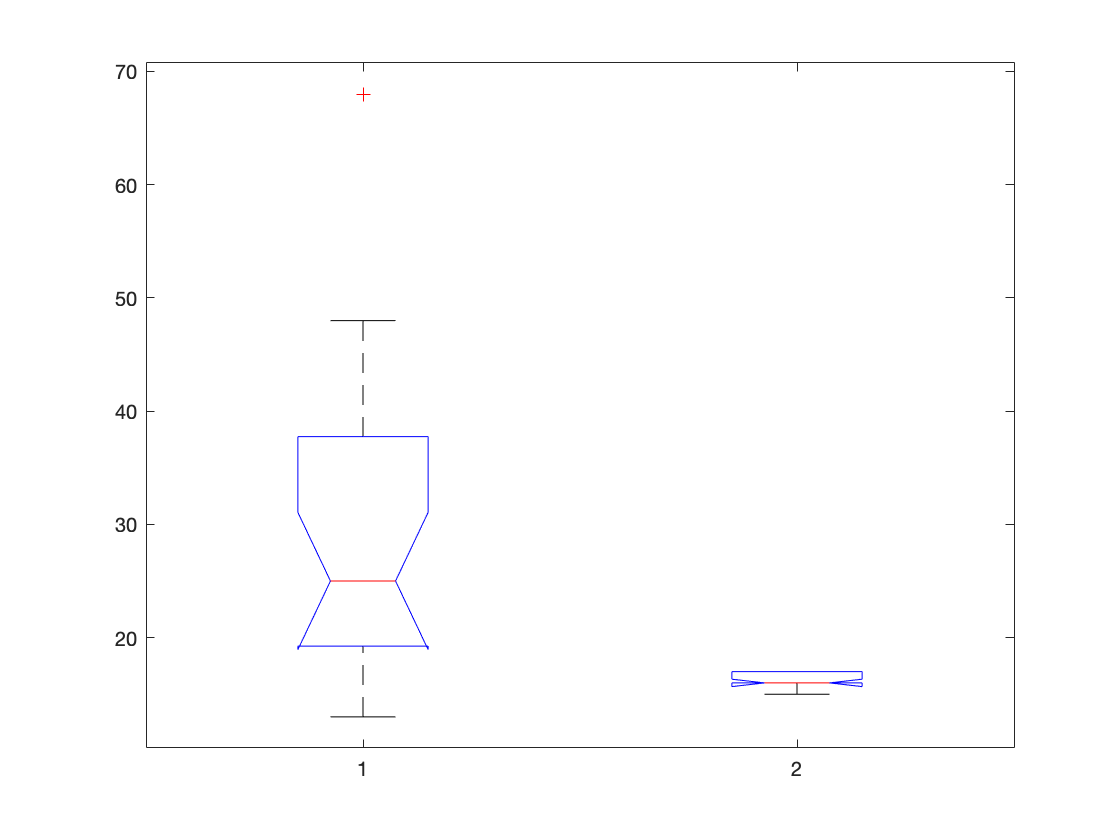

% a cell array of the absolute errors from imformation maximizing bisection
% search at each guess
deltas = {[20000, 15000, 15000, 0, 1500, 1000, 500, 400, 350, 300, 250, 200, 150, 100, 50, 30, 30, 25, 20, 15, 0, 1, 3, 3, 1] ;
[49950, 49925, 49550, 40250, 100000, 45000, 45000, 40000, 500, 0, 12150, 12140, 12130, 12120, 12110, 12101, 12100, 500, 490, 5, 145, 95, 45, 0, 15, 0, 0, 0, 1, 1, 0, 0] ;
[0, 50000, 63000, 70000, 0, 2500, 2500, 2000, 500, 0, 0, 59060, 25, 0, 5, 5, 0, 0, 1, 0] ;
[49500, 20250, 5000, 0, 5000, 8500, 11500, 500, 4000, 1000, 1500, 0, 0, 1500, 500, 500, 500, 0, 50, 0, 0, 5, 0, 5, 1, 5, 15, 352, 152, 8, 7, 6, 5, 4, 3, 2, 1, 1, 0] ;
[0, 0, 0, 1250, 1250, 21250, 1250, 1750, 750, 250, 0, 0, 13, 10, 2, 0, 1, 0] ;
[49999, 45000, 46500, 46000, 45500, 45000, 44500, 68456, 5000, 10000, 5000, 0, 5000, 0, 0, 0, 425, 475, 490, 485, 480, 475, 479, 471, 525, 475, 425, 2250, 1250, 250, 650, 150, 0, 25, 25, 75, 25, 15, 10, 50, 49, 48, 48, 47, 46, 235, 665, 615, 605, 595, 585, 575, 65, 35, 15, 5, 5, 4, 4, 3, 3, 2, 2, 1, 3, 1, 0, 0] ;
[45000, 45000, 44750, 4500, 4500, 7000, 4500, 2000, 500, 500, 499, 1, 0, 25, 49, 1, 1, 7, 6, 5, 5, 5, 4, 4, 3, 3, 2] ;
[30000, 34000, 33000, 20000, 1500, 1000, 0, 1000, 0, 0, 0, 230, 182, 188, 1, 1, 0, 0, 112, 2, 0, 73, 53, 874, 847, 472, 92, 59, 26, 14, 3, 7, 1, 0, 0] ;
[49990, 40005, 45000, 44990, 44985, 44960, 25025, 40000, 15000, 20555, 22623, 22600, 21350, 20000, 20000, 19550, 19975, 19800, 19100, 10500, 5000, 0, 5000, 4999, 4000, 3500, 3000, 1500, 1500, 1000, 500, 0, 500, 0, 150, 100, 40, 0] ;
[49999, 49900, 49950, 50, 50, 2550, 50, 550, 500, 0, 150, 100, 50, 50, 0, 3, 2, 0] ;
[0, 0, 0, 2750, 500, 500, 250, 0, 0, 75, 0, 0, 0, 12, 0, 4, 3, 0, 900, 0] ;
[0, 0, 2500, 500, 1250, 87500, 250, 250, 500, 0, 0, 0, 113, 63, 13, 20, 2, 1, 0] ;
[49500, 49500, 49500, 49504, 49501, 49502, 49500, 49500, 49500, 49499, 49499, 45500, 42500, 100000, 5000, 5000, 15000, 5000, 0, 0, 1500, 0, 0, 0, 50, 50, 0, 0, 0, 12, 64138, 3, 3, 3, 2, 2, 1] ;
[0, 0, 0, 2750, 1500, 1000, 0, 0, 0, 0, 35, 20, 0, 0, 1, 1] ;
[45000, 44500, 44000, 5000, 15000, 100000, 5000, 0, 500, 0, 499, 496, 493, 305, 400, 100, 50, 0, 50, 0, 15, 0, 2] ;
[0, 0, 0, 750, 250, 250, 0, 0, 0, 3, 13, 3, 0] ;
[0, 0, 4500, 1000, 0, 72650, 750, 500, 525, 550, 548, 550, 523, 513, 500, 500, 501, 500, 501, 500, 500, 450, 450, 452, 450, 450, 450, 450, 539, 534, 519, 499, 474, 459, 450, 449, 350, 0, 50, 25, 10, 10, 20, 0, 0, 0, 1, 0] ;
[49998, 49224, 42388, 36000, 100000, 5000, 85000, 5000, 86000, 85500, 85400, 85300, 85200, 85100, 85001, 85000, 5000, 4999, 4001, 500, 0, 500, 150, 100, 50, 0, 0, 0, 1012, 92, 188, 112, 8, 1, 1, 0] ;
[0, 0, 0, 0, 125, 250, 125, 0, 0, 0, 1, 6, 0, 2, 1, 1, 1] ;
[49500, 40250, 100000, 100000, 35000, 100000, 40000, 20000, 0, 0, 0, 250, 490, 455, 455, 445, 446, 449, 350, 0, 0, 8] ;
[0, 15000, 18800, 4400, 2500, 500, 500, 999, 501, 251, 250, 225, 50, 163, 6, 113, 37, 475, 75, 25, 0] ;
[49400, 44300, 45000, 45000, 44500, 100000, 44999, 35000, 30000, 25000, 20000, 15000, 4999, 3999, 3499, 999, 499, 499, 0, 150, 100, 50, 0, 50, 100, 75, 70, 65, 60, 60, 41, 56, 46, 16, 11, 0, 0, 2, 1] ;
[0, 0, 33750, 0, 1250, 6250, 1250, 0, 750, 500, 250, 200, 15, 10, 5, 0, 5, 7915, 7955, 7980, 7905, 7005, 6005, 5005, 3005, 1005, 1995, 2005, 1005, 5, 995, 495, 245, 95, 5, 4, 4, 2, 2, 2, 2, 1, 1]};

% deltas = deltas(~class); % by default analyze everyone

maxTurns = max(cellfun(@length, deltas));
% a matrix of where each column is a participant's error sequence
M = nan(length(deltas), maxTurns);
% plot the trajectory of the errors (both types of people)
figure
hold on
for i = 1:length(deltas)
    M(i, 1:length(deltas{i})) = deltas{i}/MAX; % normalized to [0, 1]
    % plot the normalized absolute error
    h = plot(M(i, :), 'LineWidth', 0.5, ...
        'Color', 'cyan', 'HandleVisibility', 'off');
    if i == length(deltas)
        h.HandleVisibility = 'on';
    end
end
M = M';

% create an array of the normalized delta averages
average_deltas = nanmedian(M,2);

% indicate where pure bisection search would have stopped
xline(max(machine_nTurns), ':k', 'worst case of pure bisection search', ...
    'LabelHorizontalAlignment', 'left', 'LineWidth', 2, ...
    'HandleVisibility', 'off');

% plot the smoothed average error sequence
smoothFit = fit([1:length(average_deltas)]', average_deltas, 'smoothingspline');
h = plot(smoothFit); h.LineWidth = 1; h.LineStyle = '-'; h.Color = 'blue';
% plot the linear regression function
linearFit = fit([1:length(average_deltas)]', average_deltas, 'poly1');
h = plot(linearFit); h.LineWidth = 1.5; h.LineStyle = '-'; h.Color = 'black';
% plot the power regression funtion
powerFit = fit([1:length(average_deltas)]', average_deltas, 'power2');

h = plot(powerFit); h.LineWidth = 1.5; h.LineStyle = '-'; h.Color = 'magenta';

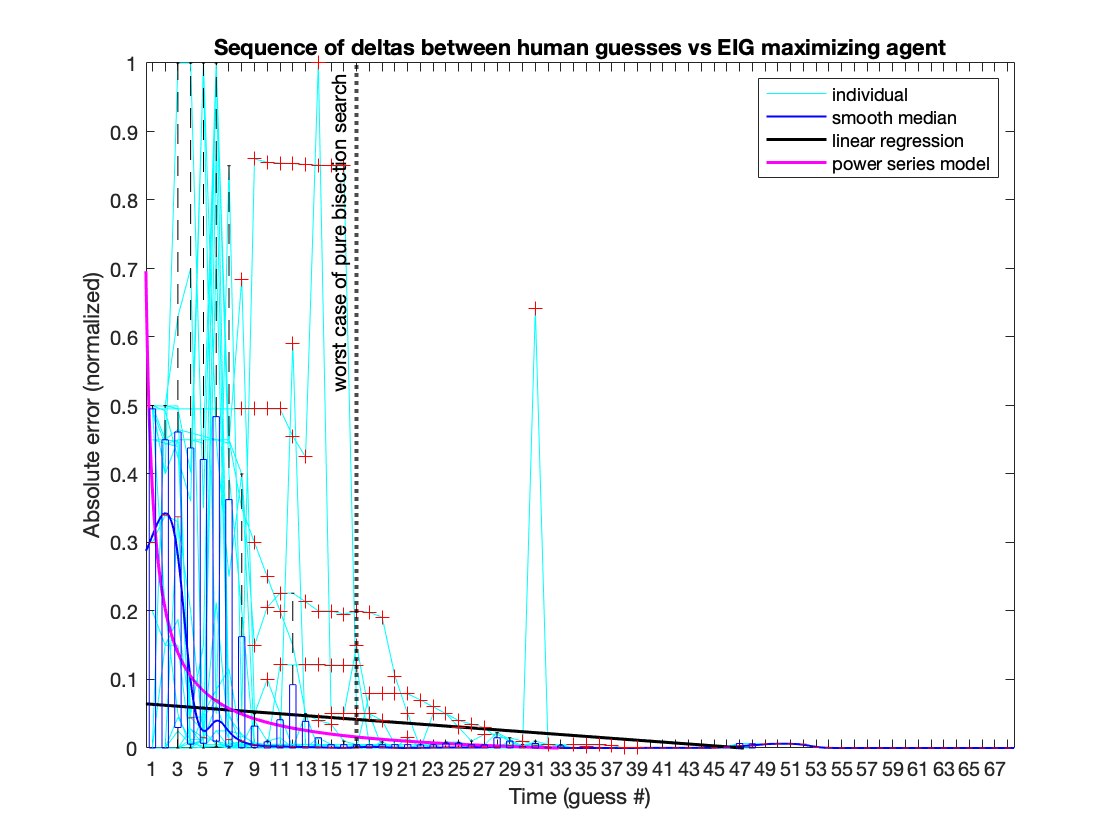

% overlay a boxplot showing the conditional expectation
boxplot(M', 'PlotStyle', 'traditional');
ax = gca; l = string(ax.XAxis.TickLabels); l(2:2:end) = nan; ax.XAxis.TickLabels = l;
% label plot and axes and add legend
title("Sequence of deltas between human guesses vs EIG maximizing agent")
xlabel('Time (guess #)')
ylim([0, 1])
ylabel('Absolute error (normalized)')
legend('individual', 'smooth median', 'linear regression', 'power series model');
hold off 

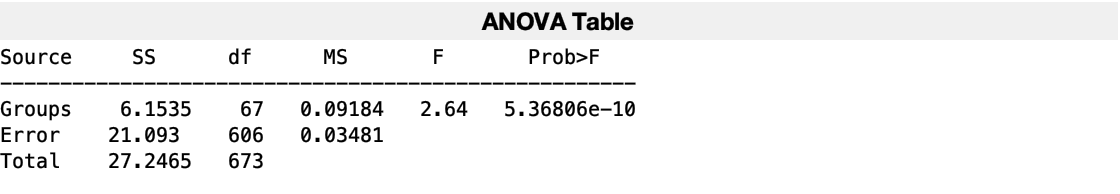

p = 5.3681e-10

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[ 6.1535]}    {[ 67]}    {[  0.0918]}    {[  2.6386]}    {[5.3681e-10]}
    {'Error' }    {[21.0930]}    {[606]}    {[  0.0348]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[27.2465]}    {[673]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {68×1 cell}
         n: [23 23 23 23 23 23 23 23 23 23 23 23 23 22 22 22 21 20 18 17 15 14 13 12 12 11 11 10 10 10 10 10 9 9 9 8 7 6 5 3 3 3 3 2 2 2 2 2 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
    source: 'anova1'
     means: [1×68 double]
        df: 606
         s: 0.1866



% PERFORM One-way anova on timepoints
% ANOVA is based on the assumption that all sample populations are normally distributed.
[p,tbl,stats] = anova1(M')

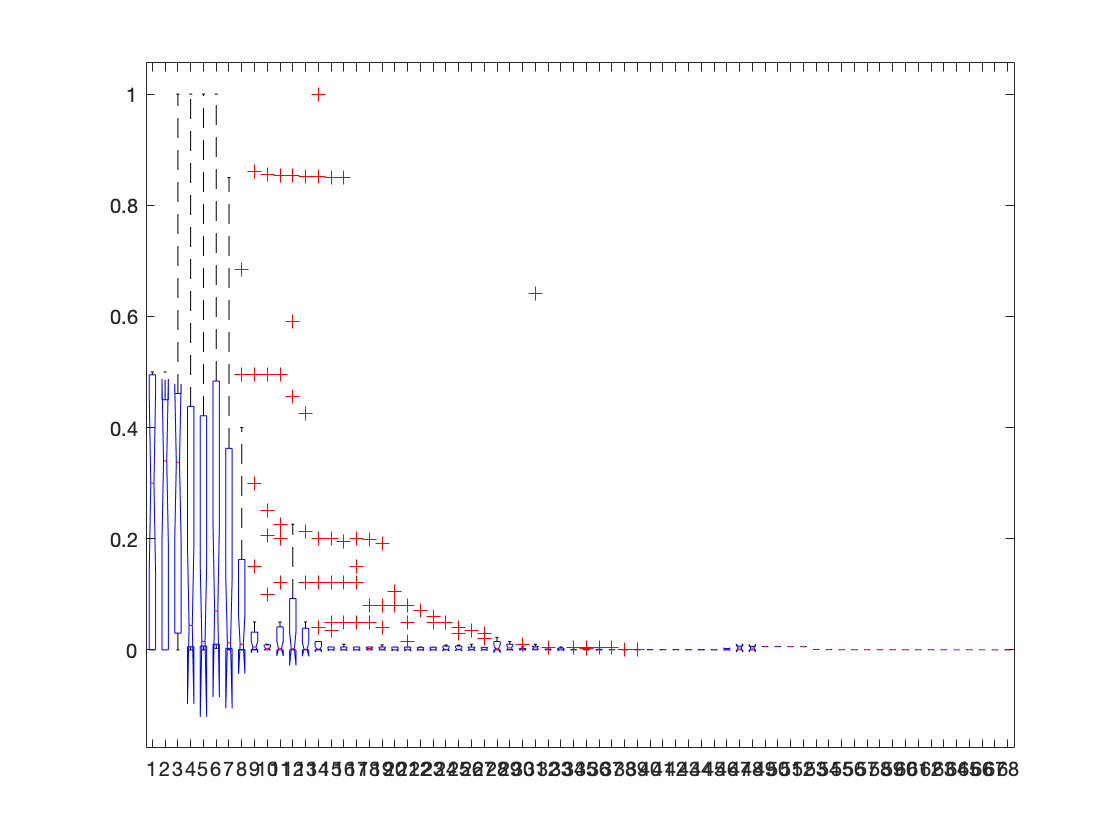

% n = length(class); % number of participants
% BtwnFactors = arrayfun(@(x) strcat('participant', num2str(x)), [1:n]', 'UniformOutput', false);
% responses = arrayfun(@(x) strcat('timept', num2str(x)), [1:maxTurns]', 'UniformOutput', false); % these are the timepoints
% t = array2table(M', 'VariableNames', responses); % create table for anova
% t.participant = BtwnFactors; % so now I have a table.
% % Fit a repeated measures model, where the timepoints are the responses and the participant is the predictor variable.
% Meas = table([1:maxTurns]','VariableNames',{'Measurements'})
% rm = fitrm(t,'timept1-timept34~participant','WithinDesign',Meas)
hold off

#### Analyze the inear regression slope and intercept

linearSlope = linearFit.p1

linearSlope = -0.0014

linearIntercept = linearFit.p2

linearIntercept = 0.0651

% observe that you get the same thing if you solve 'by hand'
X = [ones(length(average_deltas),1), [1:maxTurns]'];
Y = average_deltas;
X\Y % solving linear regression with matrices

ans =     0.0651
   -0.0014
